# Práctica 2

# Introducción al procesamiento de imágenes en MATLAB (II)

Las imágenes en MatLab se pueden obtener a partir de un fichero, tal y como se hizo en la práctica anterior, a bien por medio de:

- Cámaras definidas en el entorno Windows

- Cámaras IP

- Ficheros de video

Para ello es necesario tener instalada la toolbox de adquisición de imágenes (Image Adquisition Toolbox).

## CÁMARAS EN EL ENTORNO WINDOWS:

#### Determinar las cámaras conectadas al equipo

%imaqhwinfo
% Warning: No Image Acquisition adaptors found. To install Hardware Support Packages, use Add-On Explorer.
% For more information on which support packages to install, click here.

To install a support package, on the MATLAB **Home** tab, in the **Environment** section, click **Add-Ons > Get Hardware Support Packages**. In the Add-On Explorer, scroll to the **Hardware Support Packages** section, and click **Load more** to find your support package. You can refine the list by selecting **Imaging/Cameras** in the **Filter by Hardware Type** section on the left side of the Add-On Explorer. Select your adaptor, for example Image Acquisition Toolbox Support Package for GigE Vision Hardware or Image Acquisition Toolbox Support Package for OS Generic Video Interface, from the list.

- Instalada: MATLAB Support Package for USB Webcams

- Insltalar: Image Acquisition Toolbox Support Package for OS Generic Video Interface

%Windows Video (winvideo adaptor on videoinput object)
imaqhwinfo

ans = struct with fields:
    InstalledAdaptors: {'winvideo'}
        MATLABVersion: '23.2 (R2023b)'
          ToolboxName: 'Image Acquisition Toolbox'
       ToolboxVersion: '23.2 (R2023b)'


% webcamlist -> Cámaras web conectadas
webcamlist

ans = 1×1 cell array
    {'Integrated Camera'}


Las webcams se encuentran definidas en el adaptador ‘winvideo’

- <vble_adaptador> = imaqhwinfo(‘<nombre del adaptador>’)

adap = imaqhwinfo('winvideo')

adap = struct with fields:
       AdaptorDllName: 'C:\ProgramData\MATLAB\SupportPackages\R2023b\toolbox\imaq\supportpackages\genericvideo\adaptor\win64\mwwinvideoimaq.dll'
    AdaptorDllVersion: '23.2 (R2023b)'
          AdaptorName: 'winvideo'
            DeviceIDs: {[1]}
           DeviceInfo: [1×1 struct]


Empleando la variable de salida del adaptador podemos saber el número de cámaras conectadas, así como obtener información de cada una de ellas, en lo referente a resolución y formatos de video que admiten.

adap.DeviceInfo.SupportedFormats

ans = 1×27 cell array
    {'MJPG_1280x720'}    {'MJPG_320x180'}    {'MJPG_320x240'}    {'MJPG_352x288'}    {'MJPG_424x240'}    {'MJPG_640x360'}    {'MJPG_640x480'}    {'MJPG_848x480'}    {'MJPG_960x540'}    {'RGB24_1280x720'}    {'RGB24_320x180'}    {'RGB24_320x240'}    {'RGB24_352x288'}    {'RGB24_424x240'}    {'RGB24_640x360'}    {'RGB24_640x480'}    {'RGB24_848x480'}    {'RGB24_960x540'}    {'YUY2_1280x720'}    {'YUY2_320x180'}    {'YUY2_320x240'}    {'YUY2_352x288'}    {'YUY2_424x240'}    {'YUY2_640x360'}    {'YUY2_640x480'}    {'YUY2_848x480'}    {'YUY2_960x540'}


####  Crear un objeto cámara para realizar la captura de imágenes.

- <vble_camara> = videoinput (‘<nombre del adaptador>’ , <número de cámara>, <’formato’>);

- <vble_camara> = webcam ( <número de cámara>);

cam = webcam(1);

cam = videoinput('winvideo', 1, 'MJPG_1280x720');

####  Captura de imágenes

- <vble_imagen> = getsnapshot (<vble_camara>);

- <vble_imagen> = snapshot (<vble_camara>);

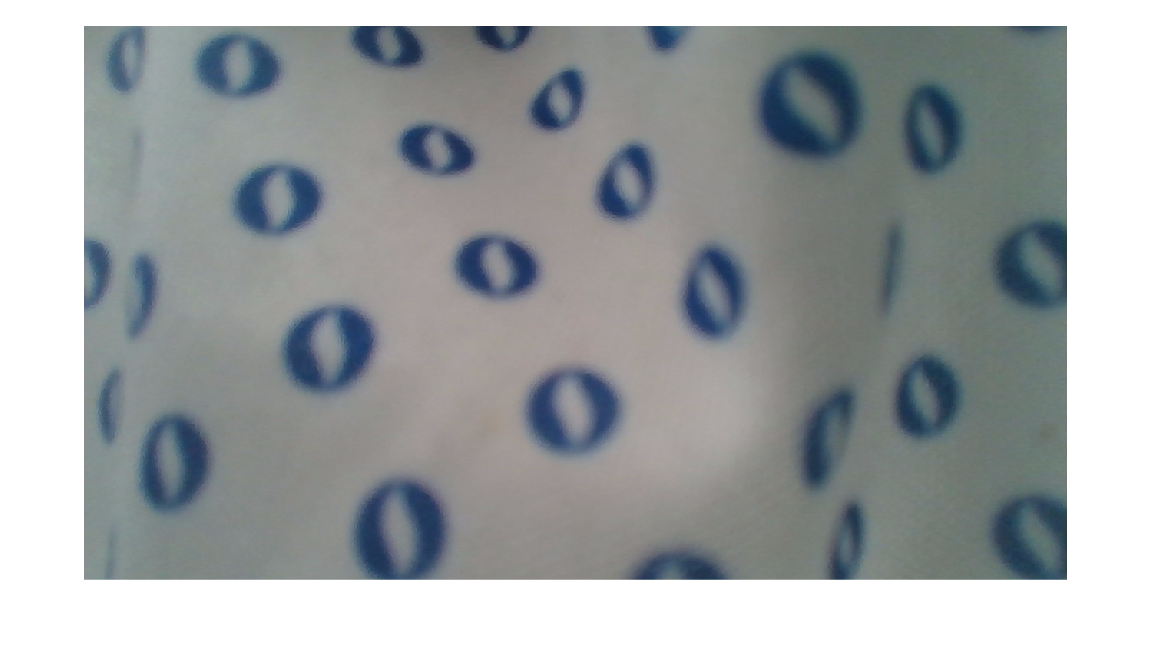

%img = snapshot(cam);
% Incorrect number or types of inputs or outputs for function snapshot.
img= getsnapshot(cam);
imshow(img);

#### Previsualización de imágenes

Es posible crear una ventana donde se muestre de forma continua las imágenes que están siendo capturadas por la cámara, sin que éstas se almacenen en ninguna variable de salida.

- preview(<vble_camara>);

- closePreview(<vble_camara>);

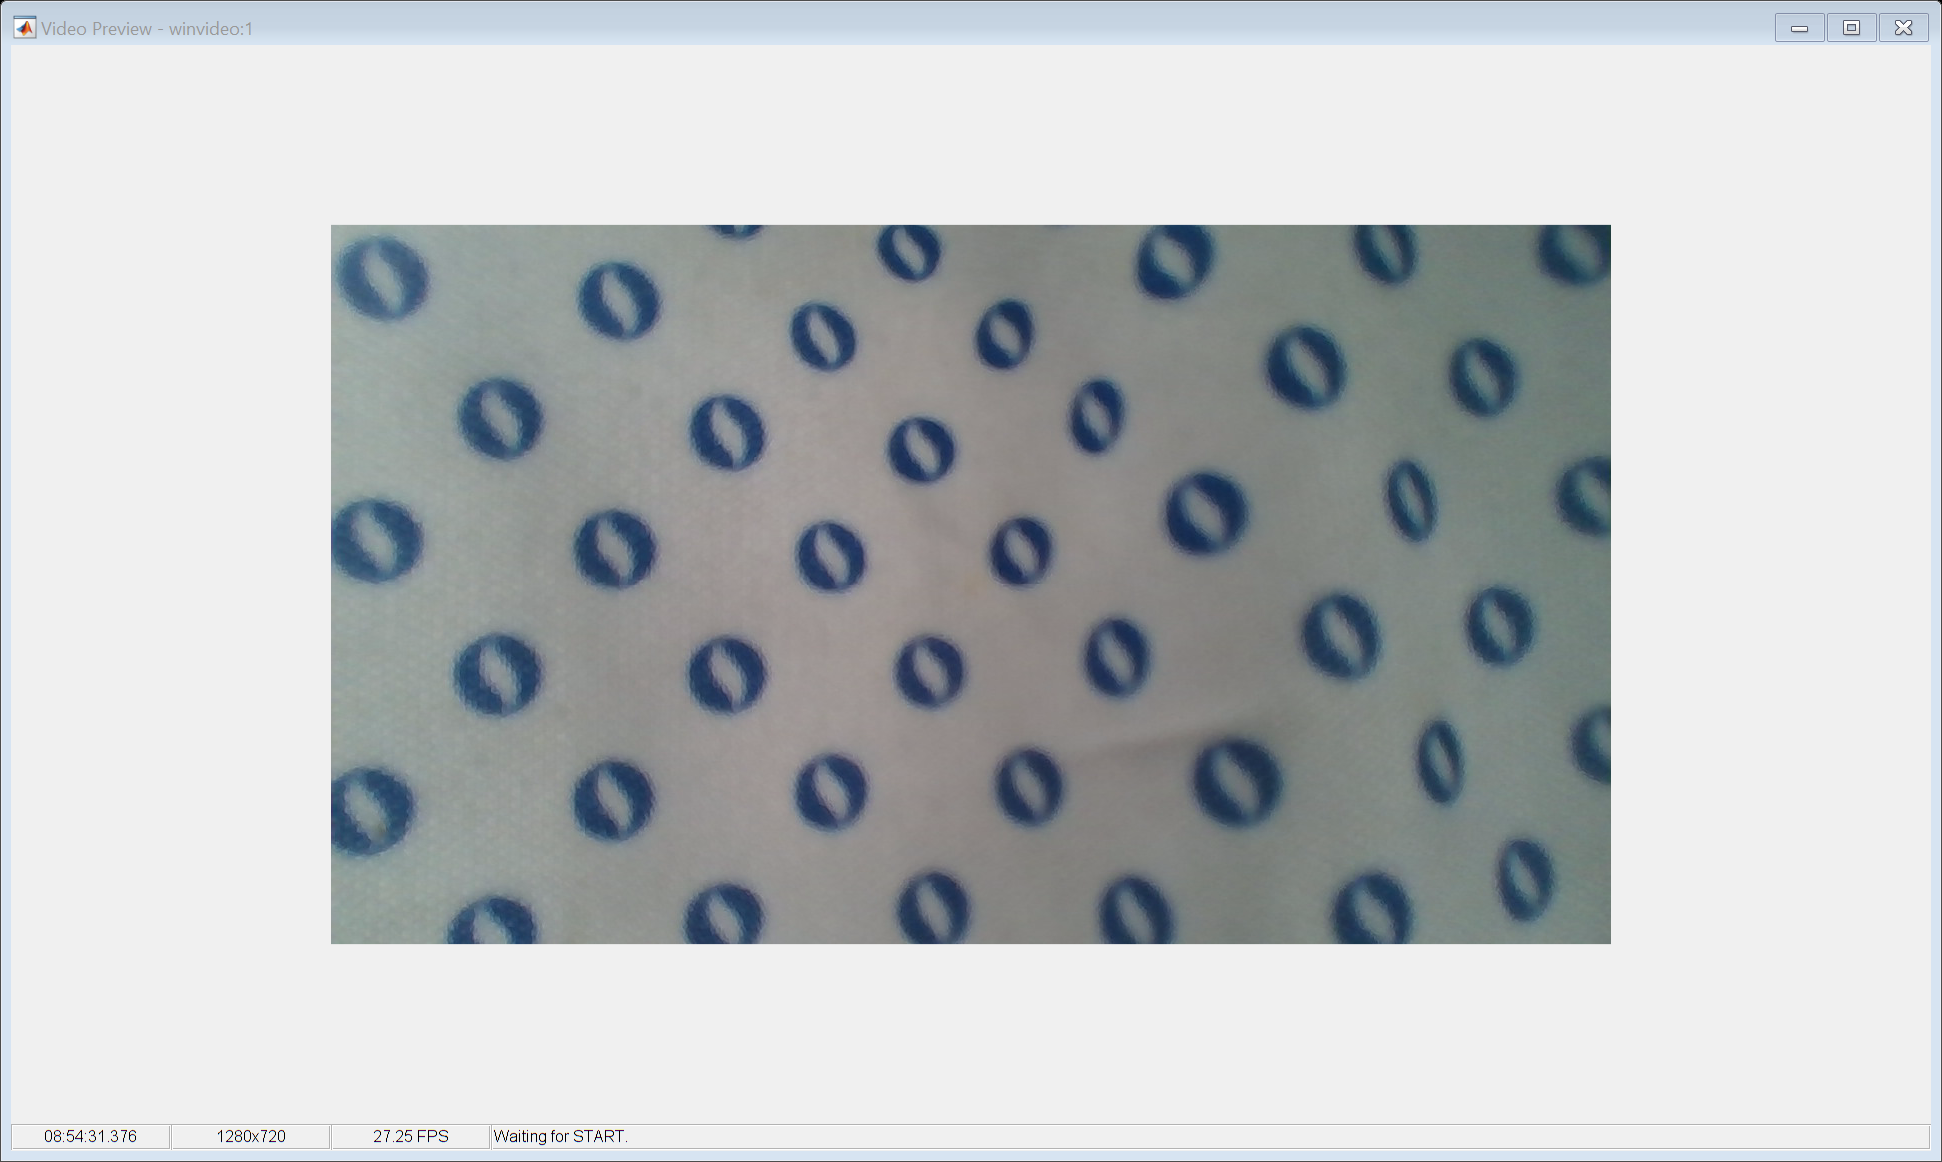

 preview(cam);

closepreview(cam);

#### CÁMARAS IP:

Para acceder a una cámara IP es necesario que su dirección se encuentre en la misma red que el equipo, ya sea directamente o bien a través de un túnel de accedo (VPN). La captura de la imagen se puede realizar leyendo de un fichero virtual (dependerá del tipo de cámara).

- < imagen> = imread (‘<dirección IP del fichero>’) ;

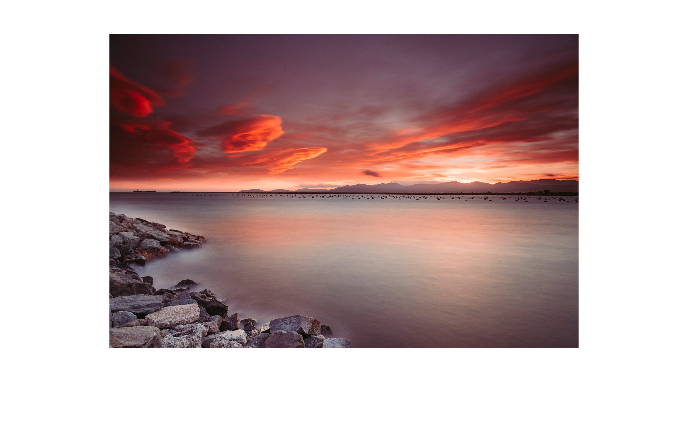

im = imread('https://mancofi.dk/srv/htdocs/wp-content/uploads/2018/01/pexels-photo-768932.jpeg');
im = im(1:4:end, 1:4:end, :);
imshow(im);

#### CARGAR IMÁGENES DESDE UN FICHERO DE VIDEO (formato estándar: mp4, mwm, avi, etc.)

- <objvideo> = VideoReader (‘<nombre de fichero>’) ; % abre fichero de video

- <imagen> = readFrame (<objvideo>) ; % lee un frame de video y pasa al siguiente

- hasFrame(<objvideo>) % TRUE si quedan frames por leer

### EJERCICIO

1. Llame a la siguiente función con los ficheros ‘cinta1_p.mp4’ y ‘cinta2_p.mp4

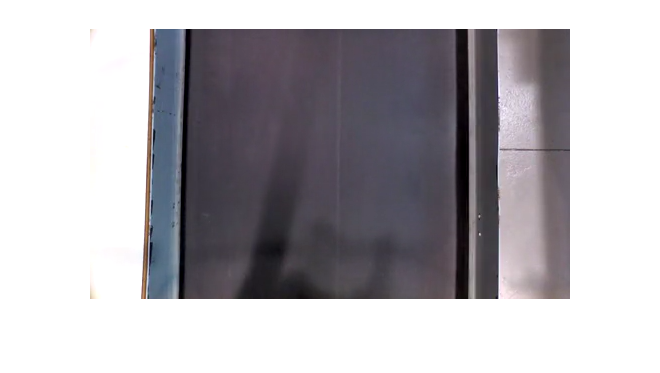

VisualizarVideo('cinta1_p.mp4') 

2. A partir de la función anterior defina una nueva función que permita visualizar el video sobre una figura junto con la diferencia de dos frames consecutivos en niveles de grises (emplear rgb2gray para realizar la conversión). Esta función permitirá detectar objetos en movimientos dentro del entorno. Compruebe su funcionamiento con el fichero ‘cinta1_p.mp4’. Multiplique la diferencia por 5 para amplificarla.

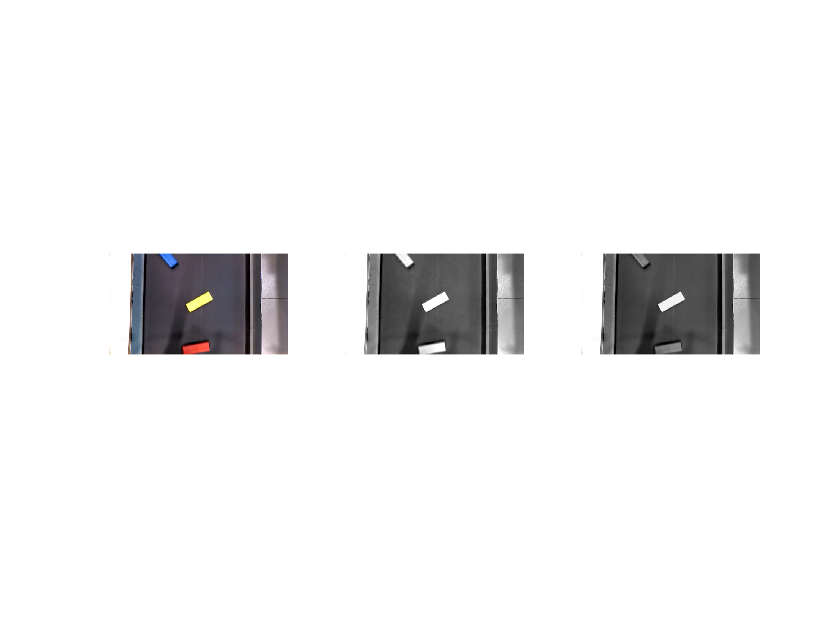

VisualizarVideo2('cinta1_p.mp4');

NOTA: compruebe que ocurre si la diferencia se amplifica multiplicándola por 25.

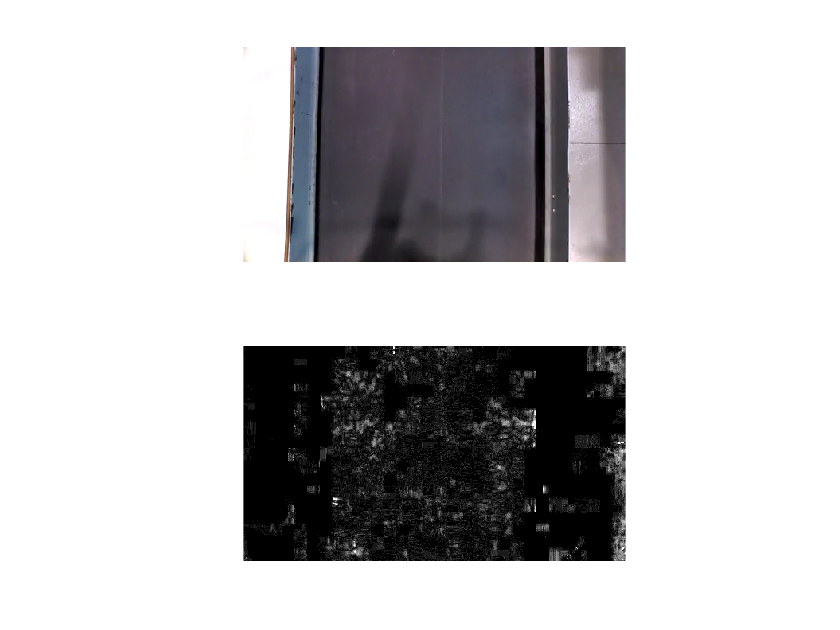

VisualizarVideo2('cinta1_p.mp4');

3. El siguiente código captura el fotograma en t = 6.6, y muestra en una figura la imagen en RGB y la conversión a niveles de grises para HSV y Luma. ¿Cuál cree que sería más adecuado para detectar las piezas independientemente de su color?

- El V de HSV permite distinguir las piezas independientemente de su color

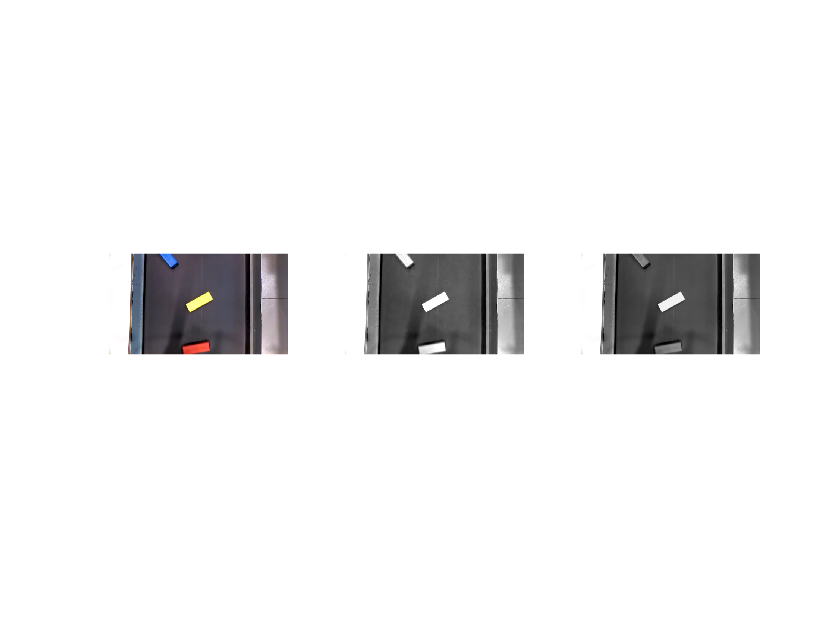

v = VideoReader('Cinta1_p.mp4');
v.currentTime = 6.6;
im66 = readFrame(v);
imHSV = rgb2hsv(im66);
V = imHSV(:,:,3);
L = rgb2gray(im66);
subplot(1,3,1); imshow(im66);
subplot(1,3,2); imshow(V);
subplot(1,3,3); imshow(L);

## DETECTAR PIEZAS:

El programa DetectarPiezas_isa (‘<nombre_fichero>’), analiza las imágenes del fichero de video de entrada y muestra la imagen y la diferencia entre una línea de referencia (sin ningún objeto) y la misma línea en sucesivas imágenes.

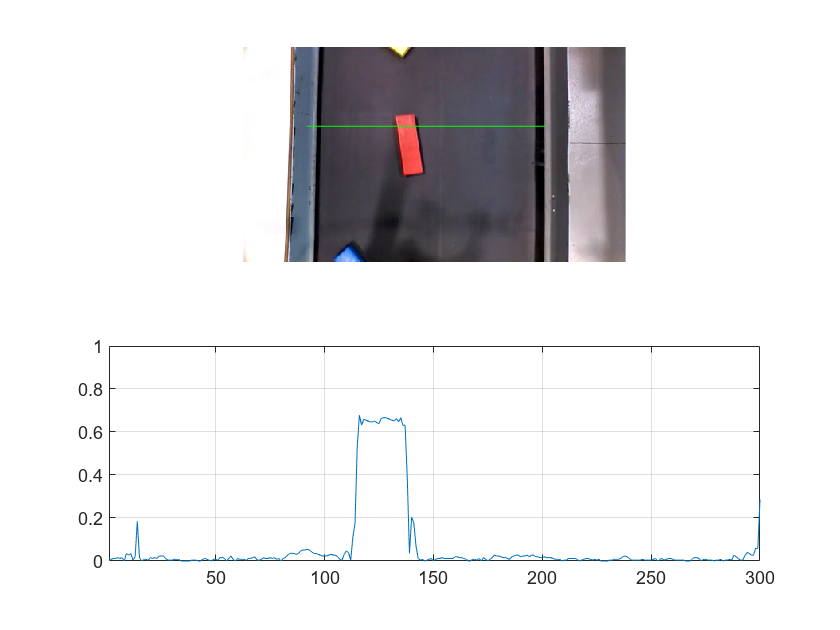

DetectarPiezas_isa('Cinta1_p.mp4');

### EJERCICIOS:

4. Analizando el resultado determine dos umbrales (umbral1 y umbral2). El primero debe representar cuanto debe variar un nivel de gris para considerar que dicho pixel ha cambiado (no es del fondo) y el segundo determina cuantos pixeles deben cambiar para que se considere que se ha detectado una pieza.

- umbral1=0.1;

- umbral2=20;

5. Compruebe si la detección de las piezas sería factible empleando las componentes H o S de la imagen HSV en lugar de la V. Para ello modifique la captura de las líneas de control.

- referencia = imHSV(100,80:380,3); %Selecciona componente V

- …

- nueva = imHSV(100,80:380,3); %Selecciona componente V

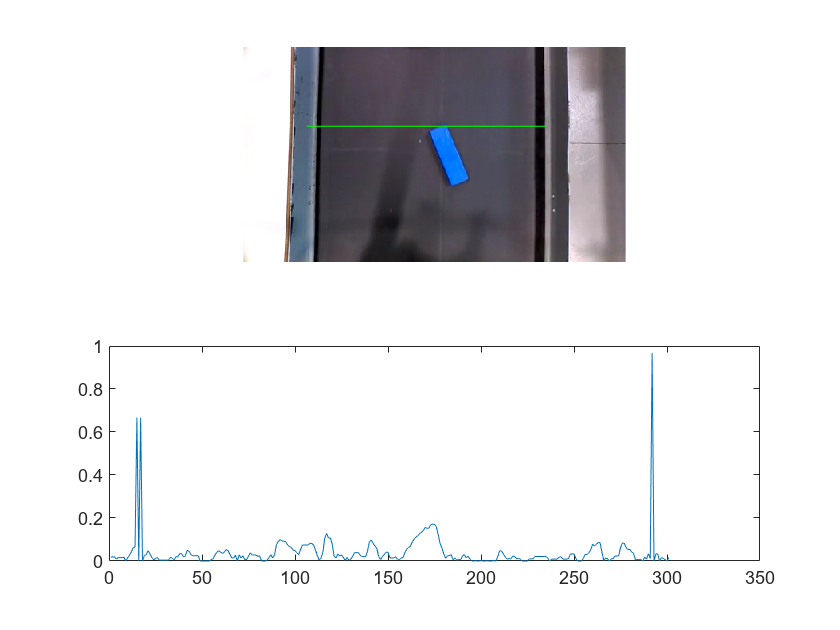

General Error occurred in WebControllerFactory::create()


DetectarPiezas_isa('Cinta1_p.mp4'); % componente H no sube de 0.2 si es azul

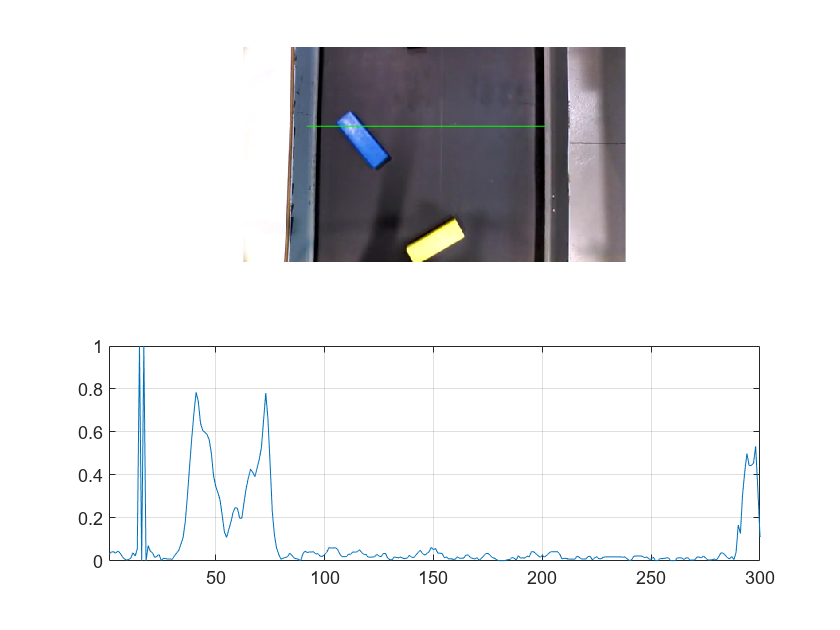

DetectarPiezas_isa('Cinta1_p.mp4'); % el brillo en la pieza provoca un valle

6. Modifique el programa original de tal forma que la línea de control se vuelva roja cuando se detecta en objeto sobre ella. Para ello debe hacer uso de los umbrales calculados en el ejercicio 3.

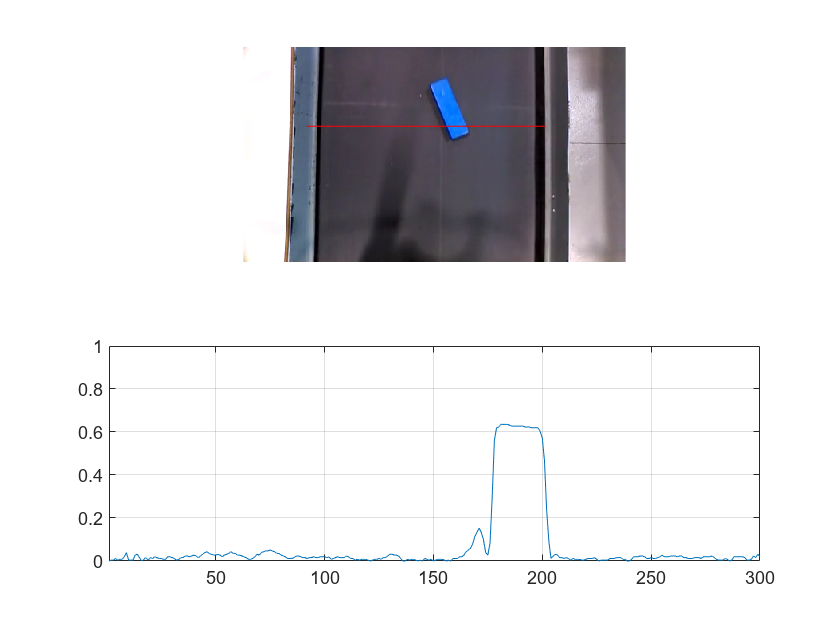

DetectarPiezas_isa('Cinta1_p.mp4'); 

7. Modifique el ejercicio anterior para que la cinta se detenga al detectar una pieza (pause). La cinta se deberá poner en marcha al pulsar una tecla y detenerse con cada nueva pieza.

NOTA: será necesario controlar cuando una pieza ya ha sido detectada y esperar a que salga para poder detectar a la siguiente.

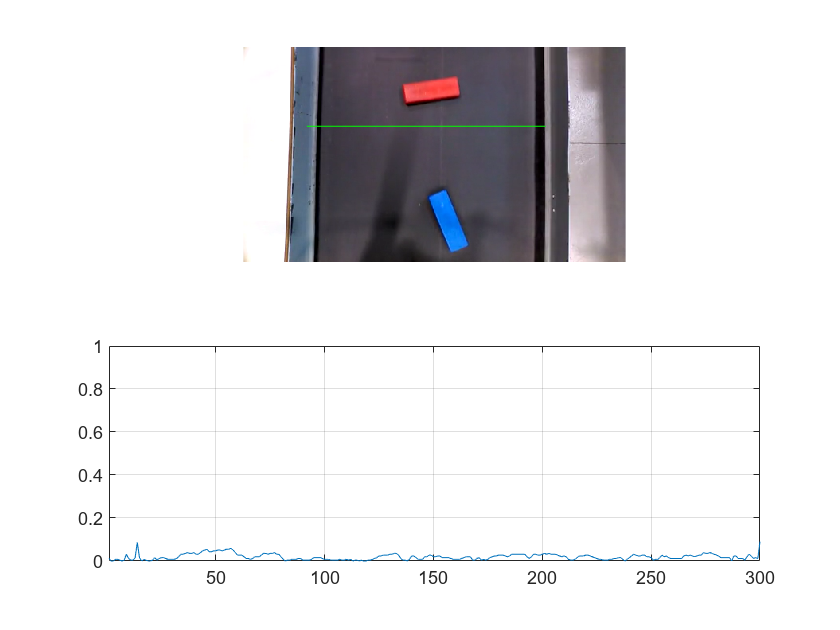

DetectarPiezas_isa('Cinta1_p.mp4'); 

8. ¿Serviría este programa para procesar las piezas de la cinta del video ‘cinta2_p.mp4’

- No. Cuando hay dos piezas a la vez no se para cuando acaba una de ellas.

## REPRODUCIR UN VIDEO (formato estándar)

- <objvideo> = implay(‘<nombre_del_fichero’); % Abre un reproductor de video

EJEMPLO

cam = implay('chinchetas.mp4');

Es posible capturar el frame que se está visualizando, accediendo directamente a la estructura de datos de la variable <objvideo>.

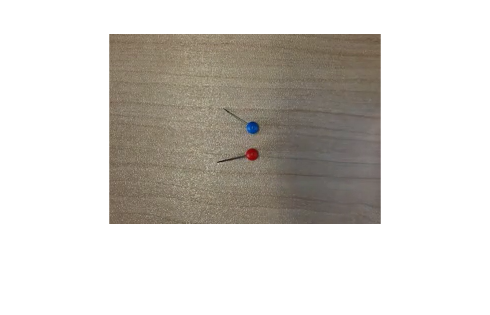

im = cam.Visual.Image.CData;
imshow(im);